mfccLength = 18;

## Blackbird vs Nightingale binary SVM classification

class1 = 'TURMER';
class2 = 'LUSMEG';

TURMER_mfcc = buildFeatureMatrix(class1,mfccLength);
LUSMEG_mfcc = buildFeatureMatrix(class2,mfccLength);

XTrain = [TURMER_mfcc;LUSMEG_mfcc];
YTrain = ones(size(XTrain,1),1);
YTrain(1:size(TURMER_mfcc,1)) = -1;

mfccLinearSvmTURMERxLUSMEG = fitcsvm(XTrain,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);

c = cvpartition(size(XTrain,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
mfccRbfSvmTURMERxLUSMEG = fitcsvm(XTrain,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

### Testing performance on unseen blackbird call

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |      0.4732 |      26.321 |      0.4732 |      0.4732 |     0.001289 |       5.0687 |
|    2 | Accept |      0.4732 |      25.719 |      0.4732 |      0.4732 |       2.3167 |     0.021367 |
|    3 | Best   |     0.42199 |      26.779 |     0.42199 |     0.42649 |       439.59 |      0.74504 |
|    4 | Best   |     0.35223 |      20.555 |     0.35223 |     0.36026 |     0.091886 |       500.03 |
|    5 | Accept |      0.3543 |      22.066 |     0.35223 |     0.35232 |     0.030563 |       534.79 |
|    6 | Accept |     0.35223 |      35.104 |     0.35223 |     

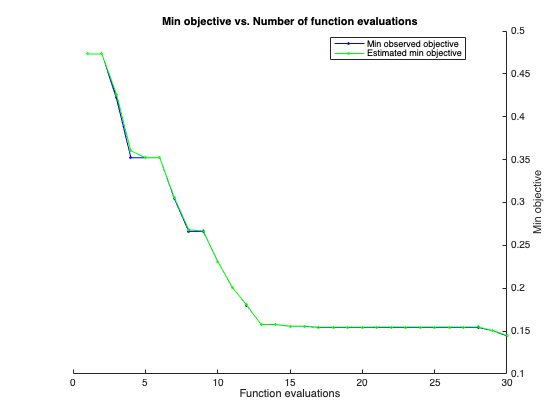

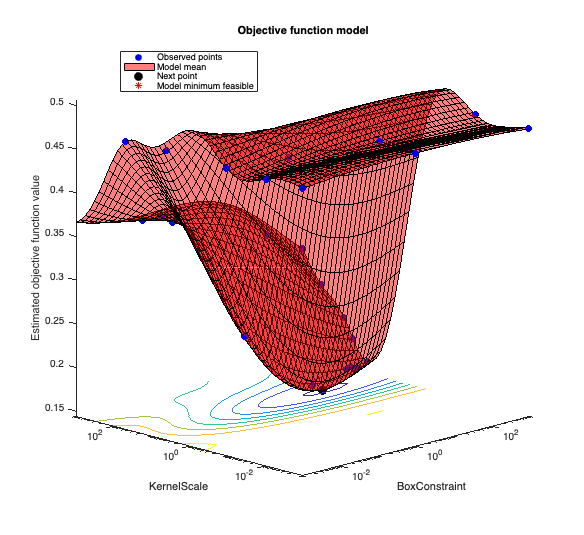


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1085.4624 seconds
Total objective function evaluation time: 1048.7459

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       37.178          11.449   

Observed objective function value = 0.14433
Estimated objective function value = 0.14502
Function evaluation time = 39.7856

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       37.178          11.449   

Estimated objective function value = 0.14502
Estimated function evaluation time = 39.2362



mfccRbfSvmTURMERxLUSMEG =   ClassificationSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [-1 1]
                       ScoreTransform: 'none'
                      NumObservations: 2910
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [1744×1 double]
                                 Bias: 0.1013
                     KernelParameters: [1×1 struct]
                       BoxConstraints: [2910×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [2910×1 logical]
                               Solver: 'SMO'


  Properties, Methods


testMatrix1 = buildFeatureMatrix(class1,18,'test',50);
[lCA, rbfCA] = testModels(testMatrix1,-1,mfccLinearSvmTURMERxLUSMEG,mfccRbfSvmTURMERxLUSMEG);
fprintf('Linear classification accuracy: %.2f%%\n', lCA*100);
fprintf('RBF classification accuracy: %.2f%%\n', rbfCA*100);

### Testing performance on unseen nightingale call

testMatrix2 = buildFeatureMatrix(class2,18,'test',50);
[lCA, rbfCA] = testModels(testMatrix2,1,mfccLinearSvmTURMERxLUSMEG,mfccRbfSvmTURMERxLUSMEG);
fprintf('Linear classification accuracy: %.2f%%\n', lCA*100);

Linear classification accuracy: 76.00%


fprintf('RBF classification accuracy: %.2f%%\n', rbfCA*100);

RBF classification accuracy: 88.00%


## Testing PCA

TURMER_mfcc = buildFeatureMatrix(class1,mfccLength);
LUSMEG_mfcc = buildFeatureMatrix(class2,mfccLength);

XTrain = [TURMER_mfcc;LUSMEG_mfcc];

Linear classification accuracy: 88.00%


YTrain = ones(size(XTrain,1),1);

RBF classification accuracy: 72.00%


YTrain(1:size(TURMER_mfcc,1)) = -1;

[XTrain95,coeffs95] = projectPCA(XTrain,95);

mfccLinearSvmTURMERxLUSMEG95 = fitcsvm(XTrain95,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);

c = cvpartition(size(XTrain95,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
mfccRBFSvmTURMERxLUSMEG95 = fitcsvm(XTrain95,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

### Testing performance on unseen blackbird call

testMatrix1 = buildFeatureMatrix(class1,18,'test',50) * coeffs95;
[lCA, rbfCA] = testModels(testMatrix1,-1,mfccLinearSvmTURMERxLUSMEG95,mfccRBFSvmTURMERxLUSMEG95);
fprintf('Linear classification accuracy: %.2f%%\n', lCA*100);
fprintf('RBF classification accuracy: %.2f%%\n', rbfCA*100);

### Testing performance on unseen nightingale call

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |      0.4732 |      2.4506 |      0.4732 |      0.4732 |    0.0053832 |        1.561 |
|    2 | Accept |      0.4732 |      1.4933 |      0.4732 |      0.4732 |     0.093757 |    0.0079754 |
|    3 | Best   |     0.31821 |      1.9054 |     0.31821 |     0.31823 |         18.8 |       42.372 |
|    4 | Accept |     0.46907 |        2.12 |     0.31821 |     0.31823 |       47.052 |    0.0011688 |
|    5 | Accept |     0.32784 |      2.3262 |     0.31821 |     0.31824 |       69.216 |       127.71 |
|    6 | Accept |     0.35876 |       1.795 |     0.31821 |     

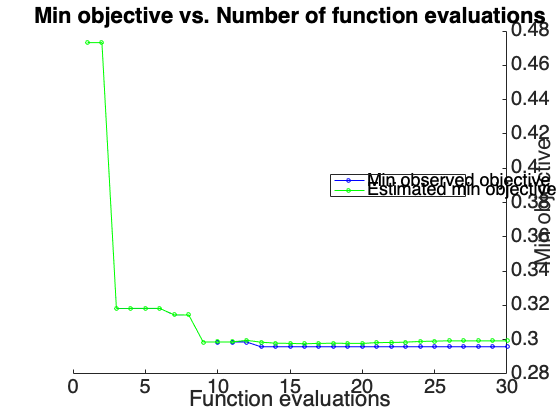

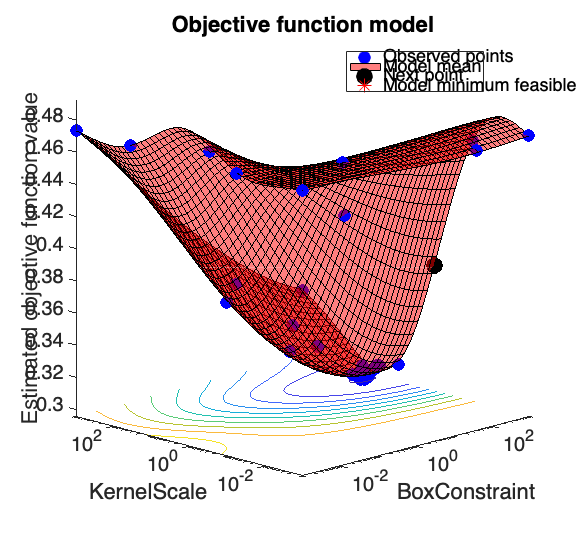


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 345.8785 seconds
Total objective function evaluation time: 311.3825

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       582.07          11.259   

Observed objective function value = 0.29588
Estimated objective function value = 0.29951
Function evaluation time = 22.2094

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       462.04          10.825   

Estimated objective function value = 0.29934
Estimated function evaluation time = 16.4463



mfccRBFSvmTURMERxLUSMEG7 =   ClassificationSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [-1 1]
                       ScoreTransform: 'none'
                      NumObservations: 2910
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [1712×1 double]
                                 Bias: 3.9748
                     KernelParameters: [1×1 struct]
                       BoxConstraints: [2910×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [2910×1 logical]
                               Solver: 'SMO'


  Properties, Methods


testMatrix2 = buildFeatureMatrix(class2,18,'test',50) * coeffs95;
[lCA, rbfCA] = testModels(testMatrix2,1,mfccLinearSvmTURMERxLUSMEG95,mfccRBFSvmTURMERxLUSMEG95);
fprintf('Linear classification accuracy: %.2f%%\n', lCA*100);
fprintf('RBF classification accuracy: %.2f%%\n', rbfCA*100);

### With 99% variance captured by PCA

[XTrain99,coeffs99] = projectPCA(XTrain,99);

mfccLinearSvmTURMERxLUSMEG99 = fitcsvm(XTrain99,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);

Linear classification accuracy: 50.00%


c = cvpartition(size(XTrain99,1),'KFold',7);

RBF classification accuracy: 70.00%


opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
mfccRBFSvmTURMERxLUSMEG99 = fitcsvm(XTrain99,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

### Testing performance on unseen blackbird call

testMatrix1 = buildFeatureMatrix(class1,18,'test',150) * coeffs99;
[lCA, rbfCA] = testModels(testMatrix1,-1,mfccLinearSvmTURMERxLUSMEG99,mfccRBFSvmTURMERxLUSMEG99);

Linear classification accuracy: 100.00%


fprintf('Linear classification accuracy: %.2f%%\n', lCA*100);

RBF classification accuracy: 66.00%


fprintf('RBF classification accuracy: %.2f%%\n', rbfCA*100);

### Testing performance on unseen nightingale call

testMatrix2 = buildFeatureMatrix(class2,18,'test',150) * coeffs99;

[lCA, rbfCA] = testModels(testMatrix2,1,mfccLinearSvmTURMERxLUSMEG99,mfccRBFSvmTURMERxLUSMEG99);
fprintf('Linear classification accuracy: %.2f%%\n', lCA*100);
fprintf('RBF classification accuracy: %.2f%%\n', rbfCA*100);

## Polynomial SVM

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |      0.4732 |      4.8765 |      0.4732 |      0.4732 |    0.0020542 |       1.5123 |
|    2 | Best   |     0.31375 |      11.335 |     0.31375 |     0.32198 |       203.54 |       1.2002 |
|    3 | Accept |     0.46598 |      2.6292 |     0.31375 |     0.32398 |       1.3253 |    0.0034273 |
|    4 | Accept |     0.34983 |      3.3511 |     0.31375 |     0.31377 |       405.41 |       931.39 |
|    5 | Accept |     0.36804 |      4.0665 |     0.31375 |     0.31377 |       93.224 |      0.48398 |
|    6 | Accept |     0.44708 |      4.8607 |     0.31375 |     

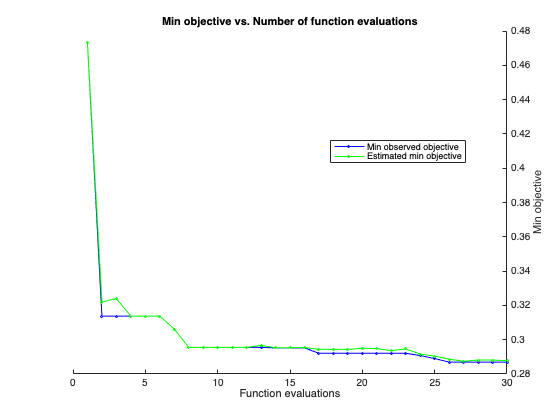

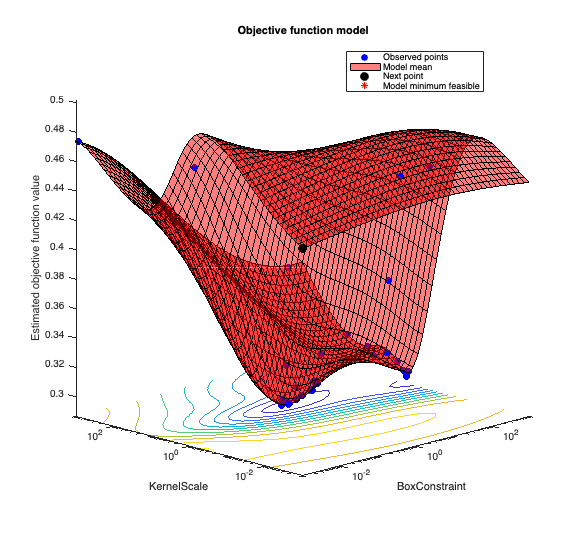


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 319.5987 seconds
Total objective function evaluation time: 285.7235

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       2.6041          6.0455   

Observed objective function value = 0.28694
Estimated objective function value = 0.28817
Function evaluation time = 1.8779

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       2.3682          5.2173   

Estimated objective function value = 0.28777
Estimated function evaluation time = 3.8038



mfccRBFSvmTURMERxLUSMEG99 =   ClassificationSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [-1 1]
                       ScoreTransform: 'none'
                      NumObservations: 2910
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [1986×1 double]
                                 Bias: 0.1391
                     KernelParameters: [1×1 struct]
                       BoxConstraints: [2910×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [2910×1 logical]
                               Solver: 'SMO'


  Properties, Methods


mfccPolySvmTURMERxLUSMEG2 = fitcsvm(XTrain,YTrain,'KernelFunction','polynomial',...
    'Standardize',true,'ClassNames',[-1,1],'PolynomialOrder',2);
mfccPolySvmTURMERxLUSMEG3 = fitcsvm(XTrain,YTrain,'KernelFunction','polynomial',...
    'Standardize',true,'ClassNames',[-1,1],'PolynomialOrder',3);

### Testing performance on unseen blackbird call

testMatrix1 = buildFeatureMatrix(class1,mfccLength,'test',150);
poly2CA = testModel(testMatrix1,-1,mfccPolySvmTURMERxLUSMEG2);
fprintf('2nd degree polynomial classification accuracy: %.2f%%\n', poly2CA*100);

Linear classification accuracy: 49.33%


poly3CA = testModel(testMatrix1,-1,mfccPolySvmTURMERxLUSMEG3);

RBF classification accuracy: 68.00%


fprintf('3rd degree polynomial classification accuracy: %.2f%%\n', poly3CA*100);

### Testing performance on unseen nightingale call

testMatrix2 = buildFeatureMatrix(class2,mfccLength,'test',150);
poly2CA = testModel(testMatrix2,1,mfccPolySvmTURMERxLUSMEG2);
fprintf('2nd degree polynomial classification accuracy: %.2f%%\n', poly2CA*100);

Linear classification accuracy: 98.00%


poly3CA = testModel(testMatrix2,1,mfccPolySvmTURMERxLUSMEG3);

RBF classification accuracy: 60.67%


fprintf('3rd degree polynomial classification accuracy: %.2f%%\n', poly3CA*100);

# ---- Helper Functions -----

function [lCA, rbfCA] = testModels(testMatrix,class,linearSVM,rbfSVM)
numTestSamples = size(testMatrix,1);
labelsLinear = predict(linearSVM,testMatrix);
lCA = sum(labelsLinear==class)/numTestSamples;
labelsRbf = predict(rbfSVM,testMatrix);
rbfCA = sum(labelsRbf==class)/numTestSamples;
end

function classificationAccuracy = testModel(testMatrix,class,model)
numTestSamples = size(testMatrix,1);

2nd degree polynomial classification accuracy: 89.33%


labels = predict(model,testMatrix);
classificationAccuracy = sum(labels==class)/numTestSamples;

3rd degree polynomial classification accuracy: 100.00%


end

function featureMatrix = buildFeatureMatrix(birdID,mfccLength,type,sampleLimit)
arguments
birdID
mfccLength = 18

2nd degree polynomial classification accuracy: 72.00%


type = 'train'
sampleLimit = false

3nd degree polynomial classification accuracy: 0.00%


end
directoryPath = sprintf('samples/%s/syllables/%s',birdID,type);
fileList = dir(fullfile(directoryPath, '*.wav'));
if sampleLimit
    limit = sampleLimit;
else
    limit = numel(fileList);
end
featureMatrix = zeros(limit,mfccLength*14*3);
for ii = 1:limit
    filePath = fullfile(directoryPath, fileList(ii).name);
    [syllable, fs] = audioread(filePath);
    featureMatrix(ii,:) = extractMfcc(syllable,fs,mfccLength);
end
end